AR = 10;
ZeroLiftAngle = 0;
TaperRatio = 0.4;
b = 19

b = 19

AoA = 0

AoA = 0

Cr = 2

Cr = 2

LiftCurveSlope = 2*pi

LiftCurveSlope = 6.2832


eval = 20

eval = 20

    
    
interval = 90/(eval)

interval = 4.5000


angles = zeros(1, eval)

angles =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles(1) = 90

angles =     90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for i = 1:eval-1
    
    angles(i+1) = 90-i*interval;
    
end

Chord = zeros(1,eval)

Chord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for i = 1:eval
    Chord(1,i) = Cr*((TaperRatio-1)*cosd(angles(i))+1);           %Fills matrix of chord values at evaluated phi locations.
end

mu = zeros(1,eval);
for i = 1:length(Chord)
    mu(1,i) = (Chord(1,i)*LiftCurveSlope)/(4*b);                  %Fills matrix of mu values using matrix of chord values.
end

Right_Coefficients = zeros(eval,eval);                                      %Initializes matrices to hold the coefficients on right and left side of lifting line equation.
Left_Coefficients = zeros(1,eval);

for i = 1:eval                                                           %Fills left and right coefficient matrices using lifting line equation.
    for j = 1:eval
        Right_Coefficients(i,j) = sind((j*2-1)*angles(1,i))*((j*2-1)*mu(1,i)+sind(angles(1,i)));
    end
    Left_Coefficients(1,i) = mu(1,i)*sind(angles(1,i));
end

A_Values = Right_Coefficients\Left_Coefficients';

delta = 0;

for x=1:eval-1
    
    delta = delta + 2*x*(A_Values(x+1)/A_Values(1))^2;
    
end

e = 1/(1+delta)

e = 0.9806


phi = zeros(1,91)

phi =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



phi(1)=0;

ClCL = zeros(1,length(phi))

ClCL =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



SumOfSines = zeros(1,length(phi))

SumOfSines =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


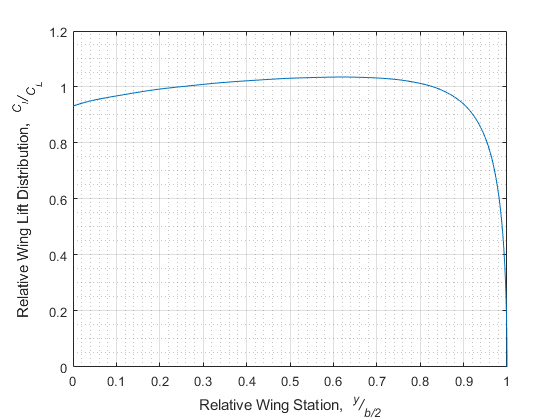


for j = 1:length(phi)-1
    
    phi(j+1)=j;
    
    for i = 1:eval
        
        SumOfSines(j+1) = SumOfSines(j+1) + A_Values(i)*sind((2*i-1)*phi(j+1));  
        
    end
    
    ClCL(j+1) = 2*(1+TaperRatio)/(pi*A_Values(1))*1/((TaperRatio-1)*cosd(j+1)+1)*SumOfSines(j+1);
  
end

y = zeros(1,length(phi));
 
y = cosd(phi);

plot(y,ClCL)

xlabel('Relative Wing Station, {\it ^{y}/_{b/2}}')

ylabel('Relative Wing Lift Distribution, {\it ^{C_l}/_{C_L}}')

grid on

grid minor



% plot(TaperRatio,e)
% xlabel('Taper Ratio, {\it \Lambda}')
% ylabel('Oswalds Efficiency Factor, {\it e}')
% grid on


 